## Image presentation and analysis

## Part C: Planet imagery

Finally, one of the more recent resources that has been made available is a commerical product from PlanetLabs. However, these are also freely accessible for research use. Let's first define the folders where the data is stored:

dirIn = 'C:\_git_local\GEO8026_21_22\Block 05\data\iceland\iceland1_psscene4band_analytic_sr_udm2\files\PSScene4Band\20210816_114330_01_2440\analytic_sr_udm2\';
filename = ...
    '20210816_114330_01_2440_3B_AnalyticMS_SR';
extension = '.TIF';

Next, let's bring the data into MATLAB:

[Bin,R]     = readgeoraster([dirIn, filename,extension]);
crs         = R.ProjectedCRS.Name; % extract the coordinate system to the var names crs
[x,y]       = pixcenters(R,abs(R.YIntrinsicLimits(2)-R.YIntrinsicLimits(1)),...
    abs(R.XIntrinsicLimits(2)-R.XIntrinsicLimits(1)));

% RGB conversions for display purposes:
bands{1} = Bin(:,:,3);   % Red channel
bands{2} = Bin(:,:,2);   % Green channel
bands{3} = Bin(:,:,1);   % Blue channel
bands{4} = Bin(:,:,4);   % NIR channel

% Optimise the bands for display
bands{1} = imadjust(bands{1}, stretchlim(bands{1}));       % Adjustment on Red channel
bands{2} = imadjust(bands{2}, stretchlim(bands{2}));       % Adjustment on Green channel
bands{3} = imadjust(bands{3}, stretchlim(bands{3}));       % Adjustment on Blue channel

% In this case we won't run the hist equalisation for this data as the visuals are okay
% without
RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization


Now we can plot the imagery, which shows two glaciers: Vatnajökull (upper left) and Skeidararjokul (right side of the image) :

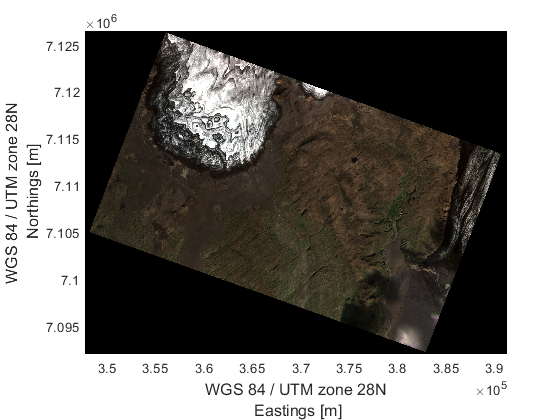

f0 = figure(); hold on;
h0 = image(x,y,RGBImage); 
set(gca, 'YDir','normal'); % we need to ensure the y-axis is correct
hXlabel = xlabel([crs ' Eastings [m]']); % Create xlabel
hYlabel = ylabel([crs ' Northings [m]']); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);
axis tight
hold off

In much the same way as we did with the Sentinel data, we can also calculate metrics from the Planet data. Let's calculate the NDWI and plot the results. However, in this instance we can see that the ice is also identified as having a high NDWI index.

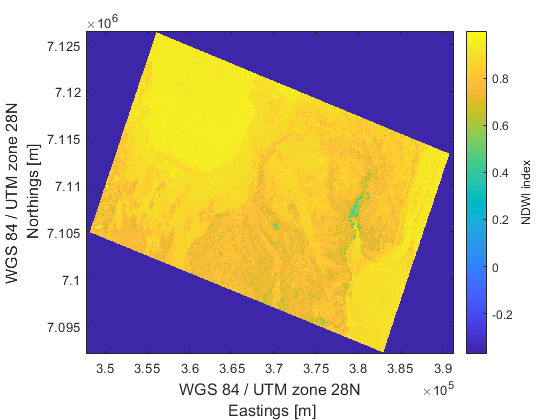

% find cells with no data
idx      = find(bands{1} == [29127] & bands{2} == [29127] & ...
    bands{3} == [29127] & bands{4} == [0] ); % find cells with no data

% calcuate the ndwi
NDWI    = (single(bands{2}) - single(bands{4} )) ./ (single(bands{2}) + single(bands{4} ));
NDWI(idx) = NaN;

% Plot the results
h1      = imagesc(x,y,NDWI); 
set(gca, 'YDir','normal'); % we need to ensure the y-axis is correct
c1          = colorbar;
ylabel(c1, 'NDWI index')
hXlabel = xlabel([crs ' Eastings [m]']); % Create xlabel
hYlabel = ylabel([crs ' Northings [m]']); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);
axis tight
hold off

Now let's run the same analysis for a different part of Iceland, noteably where the sandur (glacier outwash plain) reaches the sea. As we did last time, let's first start by defining the location where the data is stored:

dirIn = 'C:\Users\Matt\OneDrive - Newcastle University\Teaching\2021 - 22\GEO8026\Block 05\data\iceland\iceland1_psscene4band_analytic_sr_udm2\files\PSScene4Band\20210816_114334_96_2440\analytic_sr_udm2\';
filename = ...
    '20210816_114334_96_2440_3B_AnalyticMS_SR';
extension = '.TIF';

Let's load the data into MATLAB:

[Bin,R]     = readgeoraster([dirIn, filename,extension]);
crs         = R.ProjectedCRS.Name; % extract the coordinate system to the var names crs
[x,y]       = pixcenters(R,abs(R.YIntrinsicLimits(2)-R.YIntrinsicLimits(1)),...
    abs(R.XIntrinsicLimits(2)-R.XIntrinsicLimits(1)));

Now let's plot the data:

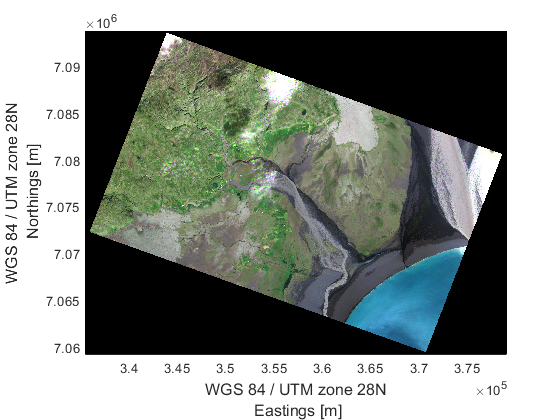

% RGB conversions for display purposes:
bands{1} = Bin(:,:,3);   % Red channel
bands{2} = Bin(:,:,2);   % Green channel
bands{3} = Bin(:,:,1);   % Blue channel
bands{4} = Bin(:,:,4);   % NIR channel

% Optimise the bands for display
bands{1} = imadjust(bands{1}, stretchlim(bands{1}));       % Adjustment on Red channel
bands{2} = imadjust(bands{2}, stretchlim(bands{2}));       % Adjustment on Green channel
bands{3} = imadjust(bands{3}, stretchlim(bands{3}));       % Adjustment on Blue channel

% We won't run the hist equalisation for this data as the visuals are okay
% without it
RGBImage = cat(3, bands{1}, bands{2}, bands{3});           % RGB image, datatype of double
RGBImage = uint8(rescale(RGBImage, 0, 255));               % Typecasted to uint8 and rescaled to 0-255 range for visualization

f2 = figure(); hold on;
h2 = image(x,y,RGBImage); 
set(gca, 'YDir','normal'); % we need to ensure the y-axis is correct
hXlabel = xlabel([crs ' Eastings [m]']); % Create xlabel
hYlabel = ylabel([crs ' Northings [m]']); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);
axis tight
hold off

We can also calculate metrics from the data. We'll calculate the NDWI and plot the results:

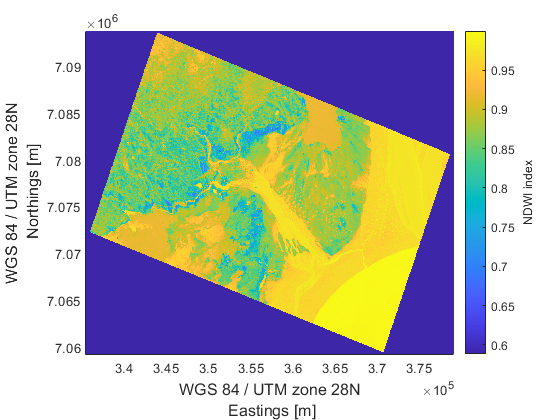

% find cells with no data
idx      = find(bands{1} == [29127] & bands{2} == [29127] & ...
    bands{3} == [29127] & bands{4} == [0] ); % find cells with no data

% calcuate the ndwi
NDWI    = (single(bands{2}) - single(bands{4} )) ./ (single(bands{2}) + single(bands{4} ));
NDWI(idx) = NaN;

% Plot the results
f3 = figure(); hold on;
h3 = imagesc(x,y,NDWI);  
set(gca, 'YDir','normal'); % we need to ensure the y-axis is correct
c3          = colorbar;
ylabel(c3, 'NDWI index')
hXlabel = xlabel([crs ' Eastings [m]']); % Create xlabel
hYlabel = ylabel([crs ' Northings [m]']); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);
axis tight
hold off

In addition to visualising the results, we can use MATLAB functions to extract areas that meet a particular threshold. In the example below, we analyse the NDWI and find all pixels that have a value > 0.94 i.e. very likely to be water. We can then find pixels that are connected to each other and begin to produce polygons of the areas that we can classify as likely to be water:

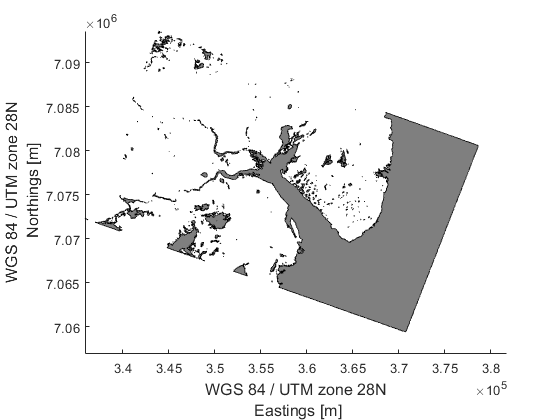

th      = 0.94; % This is the threshold
a       = NDWI(:,:,1) > th; % find pixel values greater than 0.94
a       = bwareaopen(a,100,4); % find 100+ connected pixels
B       = bwboundaries(a,'noholes');

warning('off')
f4 = figure(); hold on;
for c = 1:length(B)
    filled  = polyshape (B{c,1}(:,1),B{c,1}(:,2)); % polyshape
    if ~isempty(filled.Vertices(:,1))
        temp1   = [filled.Vertices(:,1),filled.Vertices(:,2)];
        isx     = find(~isnan(temp1(:,1)));
        dataIn  = [temp1(isx,1),temp1(isx,2)];
        filled.Vertices(isx,1:2) = [x(dataIn(:,2));y(dataIn(:,1))]'; % y then x
        plot(filled,'FaceColor','k','FaceAlpha',0.5); hold on;
    end
end

set(gca, 'YDir','normal'); % we need to ensure the y-axis is correct
hXlabel = xlabel([crs ' Eastings [m]']); % Create xlabel
hYlabel = ylabel([crs ' Northings [m]']); % Create ylabel
set([hXlabel, hYlabel]  , ...
    'FontSize',12);
axis tight
hold off